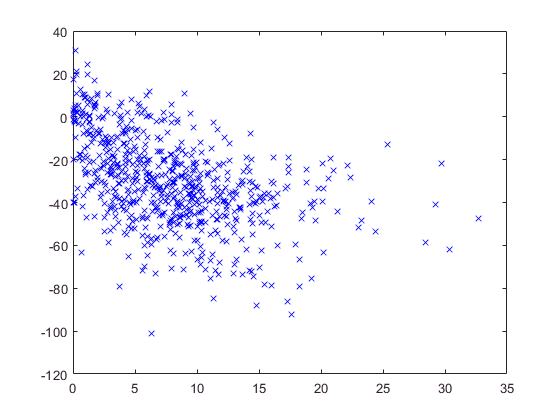

clf
%west: {1 to 6}
%east: graphdata{7 to 9}

%set some constants:
H3_index=find(strcmp(re_st,'H3')); %finds the index of the 'H3'
O18_index=find(strcmp(re_st,'O18')); %finds the index of the 'O18'
EoP_index=find(strcmp(re_st,'EndOfPeriod')); % the end of the month
BoP_index=find(strcmp(re_st,'BeginOfPeriod')); % the begining of the month

%First extract only the rows where all 3, H2,H3 amd O18 are present:


%Reading all dates

%west
H2_w={};
pppday_w={};
for i=1:6 % iterate over West
    for j=1:length(sorted{i}) % iterate  over each data point in each file 
%       H3=sorted{i}(j,H3_index);   % -----------------
        new_H2_w=sorted{i}(j,H2_index);   % get H3, H2 and O18 information for j row
%       O18=sorted{i}(j,O18_index); % -----------------
        EoP=sorted{i}(j,EoP_index); % get the date for begining to collect data
        BoP=sorted{i}(j,BoP_index); % get the date for end of collecting data
    %finding how many days the data was collected for row j 
    %(+1 because it doesn't count inclusively)
        numdays=(datenum(EoP)- datenum(BoP)+1);
    %precipitation per day
        new_pppday_w=sorted{i}{j,prec_index}./numdays;
        pppday_w=[pppday_w, new_pppday_w];
        H2_w=[H2_w,new_H2_w];
    end
end

%see a scatter plot of the data
        pppdayTable_w=cell2mat(pppday_w);
        H2Table_w=cell2mat(H2_w);
        figure(1)
        plot(pppdayTable_w,H2Table_w,'xb')
        hold off

H2_e={};
pppday_e={};
        
for i=7:9 % iterate over East
    for j=1:length(sorted{i}) % iterate  over each data point in each file 
%       H3=sorted{i}(j,H3_index);   % -----------------
        new_H2_e=sorted{i}(j,H2_index);   % get H3, H2 and O18 information for j row
%       O18=sorted{i}(j,O18_index); % -----------------
        EoP=sorted{i}(j,EoP_index); % get the date for begining to collect data
        BoP=sorted{i}(j,BoP_index); % get the date for end of collecting data
    %finding how many days the data was collected for row j 
    %(+1 because it doesn't count inclusively)
        numdays=(datenum(EoP)- datenum(BoP)+1);
    %precipitation per day
        new_pppday_e=sorted{i}{j,prec_index}./numdays;
        pppday_e=[pppday_e, new_pppday_e];
        H2_e=[H2_e,new_H2_e];
    end
end

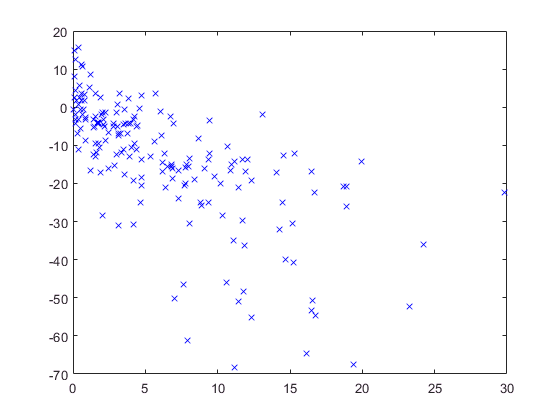


% see scatter plot of the data
        pppdayTable_e=cell2mat(pppday_e);
        H2Table_e=cell2mat(H2_e);
        figure(1)
        plot(pppdayTable_e,H2Table_e,'xb')
        hold off